## Project - Part 1 - Function approximation

### **Retrieving and plotting the data for m = 14**

The experiment data contains 2 field:

-  "id" - for identification

- "val" - for validation

Each field has:

- X - which contains x1 and x2

- Y - which contains the y values

- dimensions: 41 and 41 (for identification) and 71 and 71 (for validation)

clear
close all
[x1_ident, x2_ident, y_ident, ...
 x1_valid, x2_valid, y_valid] = get_data("proj_fit_03.mat");

#### Identification set

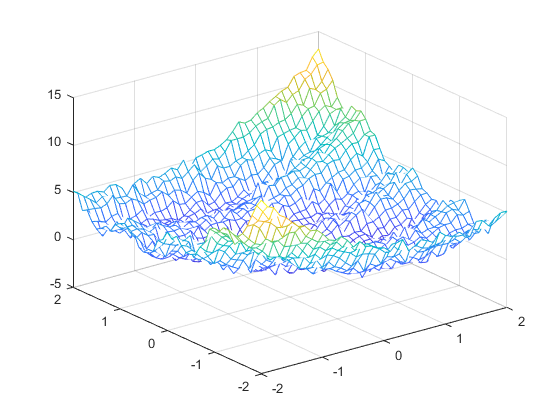

mesh(x1_ident, x2_ident, y_ident)

#### Validation set

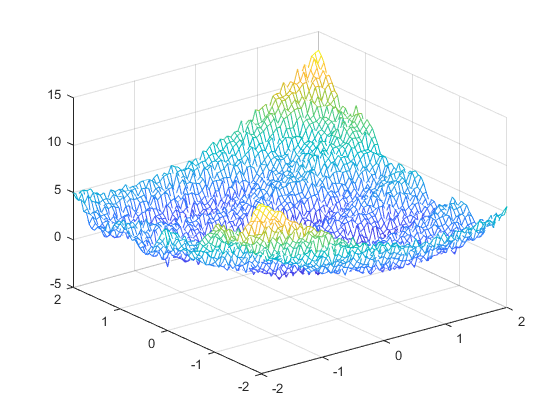

mesh(x1_valid, x2_valid, y_valid)

### Tuning the degree of the polynomial approximator

$m\in \left\lbrack \textrm{start},\textrm{stop}\right\rbrack$ - the degree of the polynomial approximator

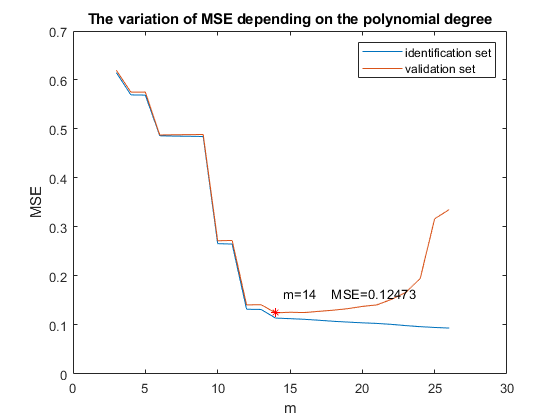

clear
close all
[x1_ident, x2_ident, y_ident, ...
 x1_valid, x2_valid, y_valid] = get_data("proj_fit_03.mat");

m_start = 3; m_stop = 26;
[mse_ident, mse_valid] = get_mse_ident_valid(x1_ident, x2_ident, y_ident, ...
                                                       x1_valid, x2_valid, y_valid, ...
                                                       m_start, m_stop);
plot_mse_ident_valid(mse_ident, mse_valid);

### Plotting the approximated function for the identification and validation set

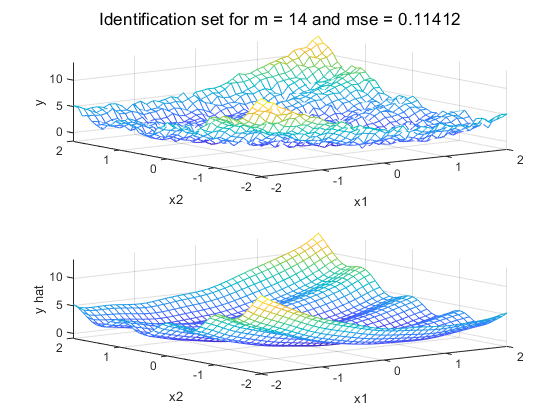

[m_best, ~] = get_best_m_mse(mse_valid);
plot_y_hat(m_best, true, x1_ident, x2_ident, y_ident, x1_valid, x2_valid, y_valid)

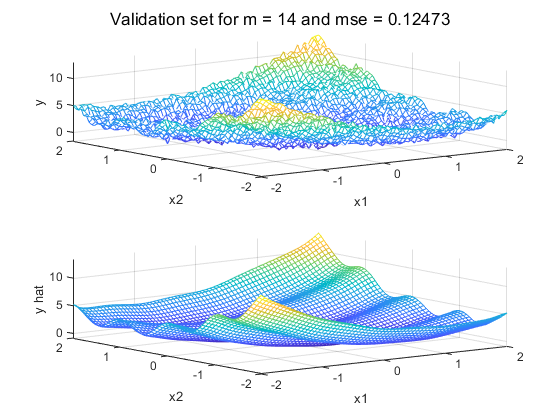

plot_y_hat(m_best, false, x1_ident, x2_ident, y_ident, x1_valid, x2_valid, y_valid)

### Comparison with `fitlm()`

clear
close all
[x1_ident, x2_ident, y_ident, ...
 x1_valid, x2_valid, y_valid] = get_data("proj_fit_03.mat");

m = 14;
Y_predicted = get_Y_predicted(m, x1_ident, x2_ident, y_ident, ...
                              x1_valid, x2_valid);
mesh(x1_valid, x2_valid, y_valid); 

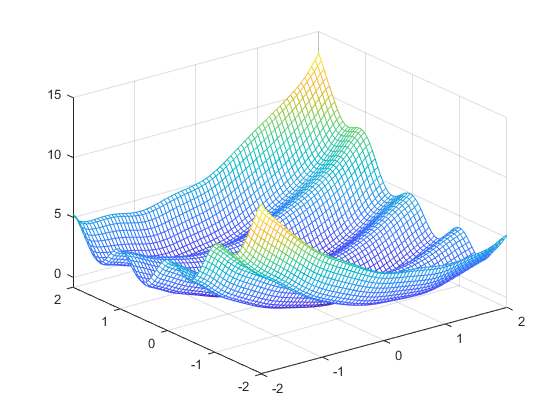

mesh(x1_valid, x2_valid, Y_predicted);

mse = get_mse(y_valid, Y_predicted)

mse = 0.1247

### Functions

#### 1 - Function that retrieves the identification and validation data

Receives the name of a file.

Returns the identification and validation data.

function [x1_ident, x2_ident, y_ident, ...
          x1_valid, x2_valid, y_valid] = get_data(file_name)

    experiment_data = load(file_name);
    ident_data = experiment_data.id;
    valid_data = experiment_data.val;
    
    X_ident = ident_data(1).X;
    x1_ident = X_ident{1};
    x2_ident = X_ident{2};
    y_ident = ident_data(1).Y;
    
    X_valid = valid_data(1).X;
    x1_valid = X_valid{1};
    x2_valid = X_valid{2};
    y_valid = valid_data(1).Y;
end

#### 2 - Function that computes the MSE

Receives two matrices $y$ and $\hat{y}$.

Returns the mean squared error, MSE, by using the following formula:

        
$$\textrm{MSE}=\frac{1}{N}\;\sum_{i=1}^N {\left(y_i -\hat{y} {\;}_i \right)}^2$$


function mse = get_mse(y, y_hat)
    mse = double(sum(sum((y - y_hat).^2))/numel(y));
end

#### 3 - Function that finds all the pairs $\left(a,b\right)$ for which $a+b\le m$

This function will be used to find the polynomial of degree $m$ in two variables, since each $a$ and $b$ represents the powers of one term of the polynomial.

Receives a number $m$.

Returns the vectors $a$ and $b$, where $a\left(i\right)$ and $b\left(i\right)$ represent one pair of powers.

function [a, b] = get_power_pairs(m)
    n = (m^2 + 3*m + 2) / 2;
    
    a = zeros(n, 1); 
    b = zeros(n, 1);
    
    index = 1;
    for i = 0 : m
        for j = 0 : m-i
            a(index) = i;
            b(index) = j;
            index = index + 1;
        end     
    end
end

#### 4 - Function that finds the polynomial of degree $m$ in two variables $x_1$ and $x_2$, with $n$ terms

Receives the degree of the polynomial $m$ and the two variables $x_1$ and $x_2$.

Returns a vector containing the terms of the polynomilal.

The number of number of terms is: $n=\frac{m^2 +3m+2}{2}$.

This function will be used for computing the matrix $\Phi$ and also the approximated function $\hat{y} \left(x_1 ,x_2 \right)$.

function poly = get_poly_two_var(m, x1, x2)
    
    [a, b] = get_power_pairs(m);
    
    poly = zeros(1, size(a, 1));
    for i = 1 : size(a, 1) 
        poly(i) = x1^a(i) * x2^b(i);
    end
end

This function is the same as the above, but it does not use preallocating. In this way, it can also be used with symbolic variables.

function poly = get_poly_two_var_syms(m, x1, x2)
    
    [a, b] = get_power_pairs(m);
    
    for i = 1 : size(a, 1) 
        poly(i) = x1^a(i) * x2^b(i);
    end
end

#### 5 - Function that computes the matrix $\Phi$ 

Receives the identification set, consisting of the two vectors that represent the indepenedent variables and the degree of the polynomial, $m$.

Returns matrix of regressors, $\Phi$.

function phi = get_phi(x1_ident, x2_ident, m)
    % number of parameters
    n = (m^2 + 3*m + 2)/2;
    
    % number of samples in the identification set
    N = size(x1_ident, 2);
    
    % index for the first and the second independent variable
    i = 1; j = 1;
    
    phi = zeros(N^2, n);    
    for k = 1 : N^2
        % complete one row of the matrix phi
        phi(k, 1 : n) = get_poly_two_var(m, x1_ident(i), x2_ident(j));
          
        % update the i index
        i = i + 1;
        
        % when k reached N, 2N, ... , N^2
        if rem(k, N) == 0
            i = 1;
            j = k/N + 1;
        end
    end
end

#### 6 - Function that computes the vector$Y$ 

Receives the dependent variable from the identification set.

Returns the vector obtained by concatenating all the columns from the original matrix.

function Y = get_Y(y_ident)
    Y = reshape(y_ident, 1, [])';
end

#### 7 - Function that computes the vector $\theta$ 

Receives the identification set, consisting of the two vectors that represent the indepenedent variables, and one vector that represents the dependent variable. It also receives the degree of the polynomial, $m$.

Returns the vector of parameters, $\theta$.

function theta = get_theta(x1_ident, x2_ident, y_ident, m)
    phi = get_phi(x1_ident, x2_ident, m);
    Y = get_Y(y_ident);
    theta = phi\Y;
end

#### 8 - Function that computes the matrix $\hat{y} \left(x_1 ,x_2 \right)$ 

Receives the parameters $\theta$, the independent variables (either from the identification or the validation set), $x_1$ and $x_2$, and the degree of the approximator polynomial, $m$.

Returns the approximated function as a matrix.

function y_hat = get_y_hat_from_theta(theta, x1, x2, m)
    % number of samples in the set
    N = size(x1, 2);
    
    % transpose the vector theta
    theta = theta';

    y_hat = zeros(N);  
    for i = 1:N 
        for j = 1:N
            % the approximated polynomial, with parameter values, as a vector
            y_hat_vector = (theta .* get_poly_two_var(m, x1(i), x2(j)));

            % the approximated polynomial, with parameter values, as a sum
            y_hat(i,j) = double(sum(y_hat_vector));
        end 
    end
end

#### 9 - Function that finds the MSEs for $m$ in a specified interval

Receives the variables for the identification and validation set, and the interval for the degree of the polynomial, $m\in \left\lbrack m_{\textrm{start}} ,m_{\textrm{stop}} \right\rbrack$.

Returns two vectors with the mean squared errors, corresponding both the identification and the validation set.

function [mse_ident, mse_valid] = get_mse_ident_valid(x1_ident, x2_ident, y_ident, ...
                                                      x1_valid, x2_valid, y_valid, ...
                                                      m_start, m_stop) 
    % preallocate to improve speed
    mse_ident = zeros(m_stop,1);
    mse_valid = zeros(m_stop,1);
    
    for m = m_start : m_stop
        % calculate the parameters on the identification set
        theta = get_theta(x1_ident, x2_ident, y_ident, m);
        
        % calculate the approximated functions on identification 
        % and validation set
        y_hat_ident = get_y_hat_from_theta(theta, x1_ident, x2_ident, m);
        y_hat_valid = get_y_hat_from_theta(theta, x1_valid, x2_valid, m);
        
        % calculate the MSEs, for each degree m, for the identification 
        % and validation set
        mse_ident(m) = get_mse(y_ident, y_hat_ident);
        mse_valid(m) = get_mse(y_valid, y_hat_valid);
    end
end

#### 10 - Function that finds the best $m$ and the best $\textrm{MSE}$ in a specified interval

Receives the mean squared error for the validation set.

Returns the smallest mean sqared error and the corresponding degree $m$.

function [m_best, mse_best] = get_best_m_mse(mse_valid)
    m = find(mse_valid);
    m_start = m(1); m_stop = m(end);

    % the degree of the polynomial for which mse is minimum
    m_best = find(mse_valid == min(mse_valid(m_start:m_stop)));
    % minimum mse
    mse_best = min(mse_valid(m_start:m_stop));
end

#### 11 - Function that plots the MSEs and the minimum M

Receives two vectors with the mean squared errors, corresponding both the identification and the validation set.

Plots the two vectors, along with the smallest mean sqared error and the corresponding degree $m$.

function plot_mse_ident_valid(mse_ident, mse_valid)
    [m_best, mse_best] = get_best_m_mse(mse_valid);
    
    plot(find(mse_ident), mse_ident(mse_ident~=0)); hold on;
    plot(find(mse_valid), mse_valid(mse_ident~=0)); 
    
    plot(m_best, mse_best, '*r');
    txt = ['m=',num2str(m_best), '    MSE=', num2str(mse_best)];
    text(m_best+0.5, mse_best+0.04, txt); hold off;
    
    xlabel('m'); ylabel('MSE');
    legend('identification set', 'validation set');
    title('The variation of MSE depending on the polynomial degree');
end

#### 12 - Function that plots the approximated function

Receives the degree $m$, along with the identification set on which the matrix $\theta$. 

If these are the only arguments, the comparison will be also made for the identification set.

Otherwise, if the validation set is also received as arguments, the comparison will be made for it.

function plot_y_hat(m, comparison_for_ident, ...
                    x1_ident, x2_ident, y_ident, ... 
                    x1_valid, x2_valid, y_valid)

    % compute theta for identification set
    theta = get_theta(x1_ident, x2_ident, y_ident, m);
    
    % check if comparison is made for identification or for validation
    if comparison_for_ident
        set_name = 'Identification set';
        x1 = x1_ident;
        x2 = x2_ident;
        y = y_ident;
    else
        set_name = 'Validation set';
        x1 = x1_valid;
        x2 = x2_valid;
        y = y_valid;
    end
    
    y_hat = get_y_hat_from_theta(theta, x1, x2, m);
    
    figure,
    subplot(211)
    mesh(x1, x2, y);
    xlabel('x1'); ylabel('x2'); zlabel('y');
    
    subplot(212);
    mesh(x1, x2, y_hat);
    xlabel('x1'); ylabel('x2'); zlabel('y hat');
    
    mse = get_mse(y, y_hat);
    sgtitle([set_name, ' for m = ', num2str(m), ' and mse = ', num2str(mse)]);
end

#### 13 - Function that arranges the two independent variables as columns in a table

Receives the two independent variables, either from the identification or the validation set.

Returns two vectors which represent the variables rearranged as columns in a table, since the `fitlm()` function expects the variables, including the dependent one, to be column vectors.

function [x1_new, x2_new] = rearrange(x1, x2)
    x1_new = [];
    for i = 1:size(x1, 2)
        x1_new = [x1_new repmat(x1(i), 1, size(x1, 2))];
    end
    x2_new = repmat(x2, 1, size(x2, 2));
end

#### 14 - Function that approximates the function using `fitlm()`

Receives the degree of the polynomial, $m$ and the identification and validation data.

Returns the predicted values for the output variable.

function Y_predicted = get_Y_predicted(m, x1_ident, x2_ident, y_ident, ...
                                       x1_valid, x2_valid)
    % get the variables in the form required by fitlm()
    % as column vectors
    [x1_train, x2_train] = rearrange(x1_ident, x2_ident);
    [x1_test, x2_test] = rearrange(x1_valid, x2_valid);
    Y_train = get_Y(y_ident);
    
    % table with the variables
    tbl = table(x1_train', x2_train', Y_train, 'VariableNames', {'x1', 'x2', 'y'});
    
    % the polynomial of degree m
    syms x1 x2
    poly = char(sum(get_poly_two_var_syms(m, x1, x2)));
    formula = strcat('y ~ ', poly);
    
    model = fitlm(tbl, formula);
    Y_predicted = model.predict([x1_test' x2_test']);
    
    % rearrange the predicted values as a matrix
    Y_predicted = reshape(Y_predicted, [size(x1_valid,2), size(x1_valid,2)]);
end